3. La siguiente ecuación diferencial, define un modelo lineal, conocido a veces como el modelo Masa-Muelle-Amortiguador


$$m\ddot y + c\dot y + ky = F(t),$$


donde $y$ es la posición del sistema, $m$ representa la masa, $c$ es un coeficiente de amortiguamiento, $k$ es una constante recuperadora, y $F\left(t\right)$ representa una fuerza externa. El modelo es genérico en el sentido de que reproduce el símil mecánico de sistemas de muy diverso tipo.

a) Obtener el modelo equivalente en variable de estados, de modo que una variable de estado sea la posición del sistema$y$ y la otra la velocidad$\dot{y}$.

Emplearemos los cambios de variable $y = x_1;\,\dot y =\dot x_1 = x_2;\, \ddot y = \dot x_2.$ De esta manera, reescribimos el sistema de la siguiente forma:


$$\dot y = \dot x_1 = x_2,\\
\ddot y = \dot x_2 = \frac{1}{m} \left[ -c x_2 - kx_1 + F(t) \right].$$


b) Simular el modelo para valores $m = 2.5\, \text{kg}$, $c = 0.6\,\text{N s m}^{-1}$ y $k = 0.4\, \text{N m}^{-1}$, empleando Matlab. Considerar los siguientes casos:

c) La señal de entrada $F$ es nula. Probar para distintos valores de las condiciones iniciales:$y\left(0\right)=1$, $\dot{y} \left(0\right)=0$; $y\left(0\right)=0$, $\dot{y} \left(0\right)=1$; $y\left(0\right)=1$, $\dot{y} \left(0\right)=1$. Representar la evolución temporal de los estado durante un intervalo de $50\,\text{s}$.

Parámetros del sistema y señal de entrada.

[m, c, k] = deal(2.5, 0.6, 0.4);
F = 0;

Primera condición inicial: $y\left(0\right)=1$, $\dot{y} \left(0\right)=0$.

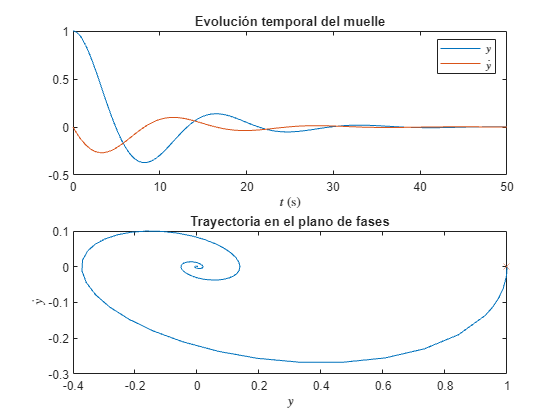

x0 = [1; 0];
t_range = [0, 50];

[t, x] = ode45( @(t,x)masa_muelle_amort(t,x,F,m,c,k), t_range, x0 );

figure(1)
clf
hold off

subplot(2,1,1)
plot(t,x)
title('Evolución temporal del muelle')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$y$','$\dot y$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$y$', 'interpreter', 'latex')
ylabel('$\dot y$', 'interpreter', 'latex')

Segunda condición inicial: $y\left(0\right)=0$, $\dot{y} \left(0\right)=1$.

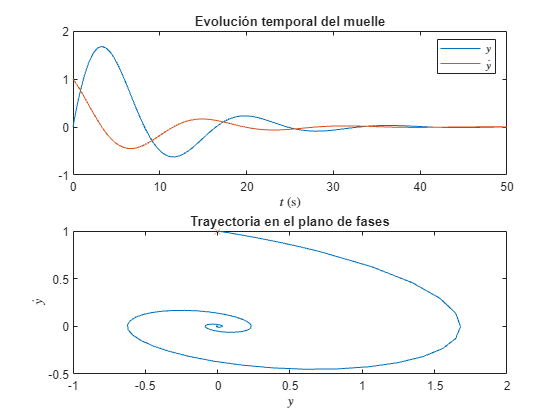

x0 = [0; 1];
t_range = [0, 50];

[t, x] = ode45( @(t,x)masa_muelle_amort(t,x,F,m,c,k), t_range, x0 );

figure(2)
clf
hold off

subplot(2,1,1)
plot(t,x)
title('Evolución temporal del muelle')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$y$','$\dot y$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$y$', 'interpreter', 'latex')
ylabel('$\dot y$', 'interpreter', 'latex')

Tercera condición inicial: $y\left(0\right)=1$, $\dot{y} \left(0\right)=1$.

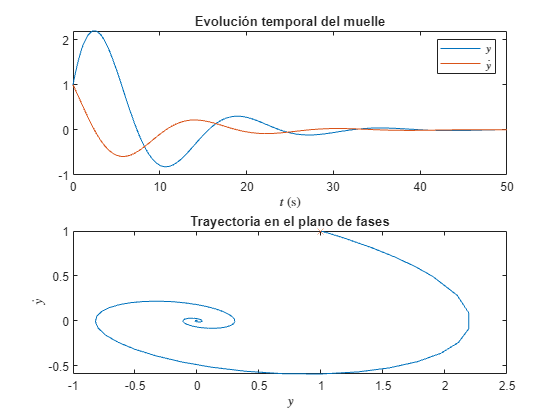

x0 = [1; 1];
t_range = [0, 50];

[t, x] = ode45( @(t,x)masa_muelle_amort(t,x,F,m,c,k), t_range, x0 );

figure(3)
clf
hold off

subplot(2,1,1)
plot(t,x)
title('Evolución temporal del muelle')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$y$','$\dot y$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$y$', 'interpreter', 'latex')
ylabel('$\dot y$', 'interpreter', 'latex')

d) La señal de entrada es una fuerza constante de $1\,\text{N}$.

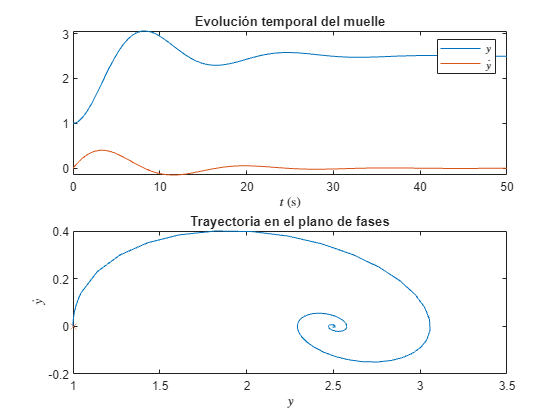

F = 1;
x0 = [1; 0];
t_range = [0, 50];

[t, x] = ode45( @(t,x)masa_muelle_amort(t,x,F,m,c,k), t_range, x0 );

figure(4)
clf
hold off

subplot(2,1,1)
plot(t,x)
title('Evolución temporal del muelle')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$y$','$\dot y$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$y$', 'interpreter', 'latex')
ylabel('$\dot y$', 'interpreter', 'latex')

e) La señal de entrada es una sinusoide de frecuencia $0.1\,\text{rad s}^{-1}$. Representar en un mismo gráfico la evolución temporal de la señal de entrada y de la señal de salida en un intervalo de $200\,\text{s}$. ¿Qué desfase se observa entre la entrada y la salida para un tiempo mayor a $50\,\text{s}$? ¿Está estabilizada la señal de salida?

En la siguiente simulación se observa un desfase de en torno a 3 segundos entre ambas señales. Debido a la señal de entrada oscilante, la señal de salida se estabiliza en torno a una órbita concreta y no un único punto de equilibrio.

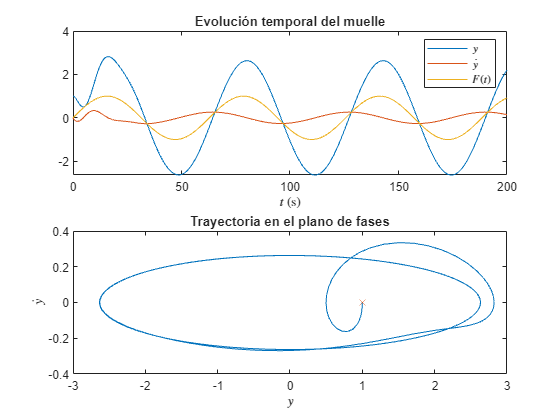

F = @(t) sin(0.1*t);

x0 = [1; 0];
t_range = [0, 200];

[t, x] = ode45( @(t,x)masa_muelle_amort(t,x,F(t),m,c,k), t_range, x0 );

figure(5)
clf
hold off

subplot(2,1,1)
plot(t,x)
hold on
plot(t, F(t))
title('Evolución temporal del muelle')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$y$','$\dot y$', '$F(t)$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$y$', 'interpreter', 'latex')
ylabel('$\dot y$', 'interpreter', 'latex')

f) Repetir el apartado e), para señales sinusoidales de frecuencias, $0.4\,\text{rad s}^{-1}$ y $1\,\text{rad s}^{-1}$ ¿Cuánto tarda en estabilizarse la señal en estos casos? ¿Qué conclusión se puede extraer del análisis de los resultados de estos dos últimos ejercicios?

Se observa que para frecuencias mayores, la salida alcanza su trayectoria estable en un menor tiempo. Sin embargo, el tiempo entre estas dos últimas frecuencias no difiere tanto como con la primera.

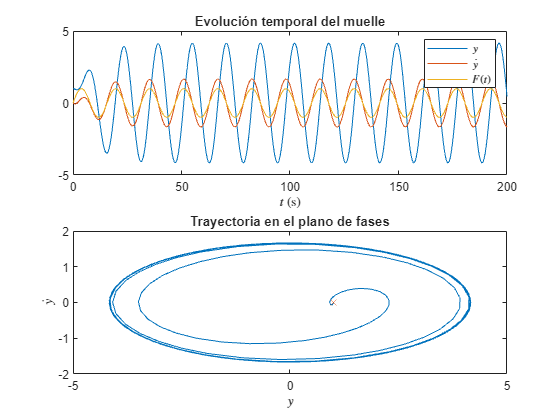

F = @(t) sin(0.4*t);

x0 = [1; 0];
t_range = [0, 200];

[t, x] = ode45( @(t,x)masa_muelle_amort(t,x,F(t),m,c,k), t_range, x0 );

figure(6)
clf
hold off

subplot(2,1,1)
plot(t,x)
hold on
plot(t, F(t))
title('Evolución temporal del muelle')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$y$','$\dot y$', '$F(t)$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$y$', 'interpreter', 'latex')
ylabel('$\dot y$', 'interpreter', 'latex')

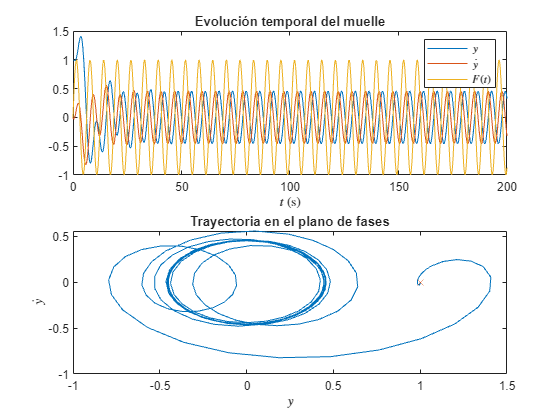

F = @(t) sin(1*t);

x0 = [1; 0];
t_range = [0, 200];

[t, x] = ode45( @(t,x)masa_muelle_amort(t,x,F(t),m,c,k), t_range, x0 );

figure(7)
clf
hold off

subplot(2,1,1)
plot(t,x)
hold on
plot(t, F(t))
title('Evolución temporal del muelle')
xlabel('$t$ (s)', 'interpreter', 'latex')
legend('$y$','$\dot y$', '$F(t)$','interpreter','latex')

subplot(2,1,2)
plot(x(:,1), x(:,2))
hold on
plot(x0(1,1), x0(2,1), 'x')
title('Trayectoria en el plano de fases')
xlabel('$y$', 'interpreter', 'latex')
ylabel('$\dot y$', 'interpreter', 'latex')

function xdot = masa_muelle_amort(t, x, F, m, c, k)
    xdot(1,1) = x(2,1);
    xdot(2,1) = ( -c*x(2,1) - k*x(1,1) + F ) / m;
end